## Example with triangles

Mesh:

clear;
x1 = linspace(0,1,2);
x2 = linspace(0,1,2);

[xv,yv] = meshgrid(x1,x2);

[F,V] = mesh2tri(xv,yv,zeros(size(xv)),'x');

m.coord  = V(:,1:2);
m.connec = F;
mesh     = Mesh(m);

ls = [-1;-1;-1;-1;1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh = UnfittedMesh(sUm);
uMesh.compute(ls);

Function:

s.fValues = [0;0.5;1;1.5;1];
s.mesh    = mesh;
fBackgr   = P1Function(s);

Function values of new nodes:

fun = uMesh.obtainFunctionAtCutMesh(fBackgr);

## Example with quads

clear;

Mesh:

mesh = UnitQuadMesh(2,2);

ls = [-1;-1;-1;-1;1;-1;-1;-1;-1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh = UnfittedMesh(sUm);
uMesh.compute(ls);

Function:

s.fValues = [0;0.25;0.5;0.5;1;1;1;1.25;1.5];
s.mesh    = mesh;
fBackgr   = P1Function(s);

Function values of new nodes:

fun = uMesh.obtainFunctionAtCutMesh(fBackgr);

## Example with tetrahedra

clear;

Mesh:

X    = [0 ,0, 0;...
        1, 0, 0;...
        0, 1, 0;...
        1, 1, 0;...
        0, 0, 1;...
        1, 0, 1;...
        0, 1, 1;...
        1, 1, 1;];
tri  = delaunay(X);
s.coord = X;
s.connec = tri;
mesh = Mesh(s);

ls = [-1;-1;-1;-1;1;1;1;1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh = UnfittedMesh(sUm);
uMesh.compute(ls);

Function:

s.fValues = [0;1;1;2;1;2;2;3];
s.mesh    = mesh;
fBackgr   = P1Function(s);

Function values of new nodes:

fun = uMesh.obtainFunctionAtCutMesh(fBackgr);

## Example with hexahedra

clear;

Mesh:

s.coord = [0 ,0, 0;...
        1, 0, 0;...
        0, 1, 0;...
        1, 1, 0;...
        0, 0, 1;...
        1, 0, 1;...
        0, 1, 1;...
        1, 1, 1;];
s.connec = [1,2,4,3,5,6,8,7];
mesh = Mesh(s);

ls = [-1;-1;-1;-1;1;1;1;1];

sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh = UnfittedMesh(sUm);
uMesh.compute(ls);

Function:

s.fValues = [0;1;1;2;1;2;2;3];
s.mesh    = mesh;
fBackgr   = P1Function(s);

Function values of new nodes:

fun = uMesh.obtainFunctionAtCutMesh(fBackgr);

## Unfitted mesh function with quads (example)

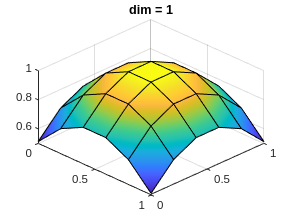

clear;


mesh = UnitQuadMesh(5,5);
ls   = -1*ones(mesh.nnodes,1);
ls([15,16,21,22]) = 2;
sUm.backgroundMesh = mesh;
sUm.boundaryMesh   = mesh.createBoundaryMesh;
uMesh = UnfittedMesh(sUm);
uMesh.compute(ls);


sAF.fHandle = @(x) 1-(x(1,:,:)-0.5).^2-(x(2,:,:)-0.5).^2;
sAF.ndimf   = 1;
sAF.mesh    = mesh;
aFun       = AnalyticalFunction(sAF);
aFun.plot();
view(45,45);

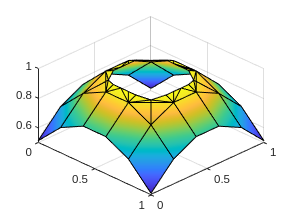



sUmf.uMesh    = uMesh;
sUmf.levelSet = ls;
uMeshFun      = UnfittedMeshFunction(sUmf);
uMeshFun.compute(aFun);
uMeshFun.plot();
view(45,45);